# Fundamental Theorem of Calculus

[⇦ Overview](matlab: OpenOverview)

One profound connection between differential and integral calculus is the relationship between [accumulation functions](matlab:open('./integralRiemann.mlx')) and [derivative functions](https://github.com/MathWorks-Teaching-Resources/Calculus-Derivatives). 

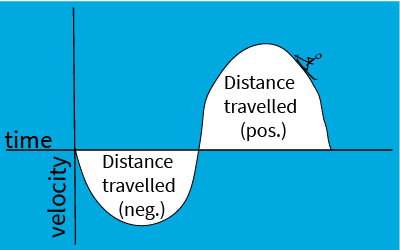

The geometric area under a curve corresponds to the total accumulation of the product of the values tracked along each axis. In this image velocity times time is distance. 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.

clear
 

## Fundamental Theorem of Calculus, Derivative Form

Let $\displaystyle g(x) = \int_a^x f(t)\; dt$. Then

 
$$\frac{d}{dx}\left[g(x)\right] = \frac{d}{dx}\left[\int_a^x f(t)\; dt\right]$$
                                                   

 
$$= \lim_{\epsilon \to 0}\frac{\int_a^{x+\epsilon}f(t)\; dt - \int_a^{x}f(t)\; dt}{\epsilon}$$
               

       
$$=\lim_{\epsilon \to 0} \frac{\int_{x}^{x+\epsilon}f(t)\;dt + \int_a^{x}f(t)\; dt - \int_a^x f(t)\; dt}{\epsilon}$$


              
$$=\lim_{\epsilon \to 0}\frac{\int_x^{x+\epsilon}f(t)\; dt}{\epsilon} = \lim_{\epsilon \to 0} \frac{f(x)\cdot (x+\epsilon-x)}{\epsilon} = f(x)$$


figure
clear f
syms t
f(t) =  t^2;
a = -2;
x = 3;

To consider a limit as $\epsilon \to 0$, it is important to consider both positive and negative values of `epsilon`. To facilitate a close approach to zero, the slider allows you to set the exponent $n$ in the expression $\epsilon = 10^n$ so the slider presents values from about 1.26 to 1e-8. 

epsNeg = false;    epsExp = 0;
epsilon = (-1)^epsNeg*10^(epsExp);
tAll = -5:.01:5;
plot(tAll,f(tAll),"k-")
ax = gca;
hold on
if a <= x
    % If integration is left-to-right, color the base area in blue
    tVals = a:.01:x;
    colChoice = "#0072BD";
else
    % If the integration is right-to-left, color the base area in orange
    % and print a warning
    tVals = x:.01:a;
    colChoice = "#D95319";
    warning("You are inverting the direction of integration from left-to-right to right-to-left")
end
leftmax = min(a,x);
rightmin = max(a,x)+.1;

Use these controls to zoom in on your region of interest:

xleft = -5;
xright = 5;

% Fix the extraArea color to be golden
coleChoice = "#EDB120";
yVals = f(tVals);
tpeVals = linspace(x,x+epsilon,50);
ypeVals = f(tpeVals);
baseArea = area(tVals,yVals,"FaceColor",colChoice);
extraArea = area(tpeVals,ypeVals,"FaceColor",coleChoice);
xlim([xleft xright])
fxVal = double(vpa(subs(f,x)));
areaVal = double(vpa(int(f,t,x,x+epsilon)))/epsilon;
%intfVal = int(f,t,x,x+eps);
topyVal = ax.YLim(2)+1/20*(ax.YLim(2)-ax.YLim(1));
bottomyVal = ax.YLim(1)-1/10*(ax.YLim(2)-ax.YLim(1));
leftxVal = xleft+.1*(xright-xleft);
midxVal = (xleft+xright)/2;
bottomxVal = xleft+.4*(xright-xleft);
text(leftxVal,topyVal,"$f(x) = $"+fxVal,"Interpreter","latex")
text(midxVal,topyVal,"$\left(\int_x^{x+\epsilon} f(t)\; dt\right)/\epsilon =$ "+areaVal,"Interpreter","latex")
text(bottomxVal,bottomyVal,"$\epsilon = $"+epsilon,"Interpreter","latex")
hold off

  **Try**.

- What happens to the yellow component of your plot when you reduce the size of epsilon? What do you notice about the values of $f(x)$ and $\displaystyle \left(\int_x^{x+\epsilon}f(t)\; dt\right)/\epsilon$?

- What happens to the yellow component of your plot when you consider a negative value of epsilon rather than a positive one? What do you notice about the values of $f(x)$ and $\displaystyle \left(\int_x^{x+\epsilon}f(t)\; dt\right)/\epsilon$?

- Why do you think this is called the derivative form of the Fundamental Theorem of Calculus?

## Fundamental Theorem of Calculus, Antiderivative Form

$\displaystyle F(x) = C+ \int_{-\infty}^x f(t)\; dt$ is the total amount accumulated from the beginning of time up to the point $x$ plus an arbitrary constant $C$. Then the total amount accumulated between $t=a$ and $t=b$ is 


$$\int_a^b f(t)\; dt = \int_{-\infty}^b f(t)\; dt - \int_{-\infty}^a f(t)\; dt = \left(C+ \int_{-\infty}^b f(t)\; dt\right) - \left(C+ \int_{-\infty}^a f(t)\; dt\right) = F(b)-F(a).$$


That is, the amount accumulated between $a$ and $b$ is the total amount that accumulated from the beginning of time up until time $b$ minus everything that had accumulated from the beginning of time up until $a$. 

figure
syms t
f(t) = sin(t);
a = -2;
b = 1;
C = 0;
areaFlag = false;
if ~exist("tAll","var")
    tAll = -5:.01:5;
end
F(t) = int(f,t);
FAVal = double(subs(F,a)+C);
FBVal = double(subs(F,b)+C);
plot(tAll,f(tAll),"k-")
ax = gca;
hold on
if a <= b
    % If area is accumulated to the right of a, color the area in blue
    tVals = a:.01:b;
    colChoice = "#00a9e0";
else
    % If the integration is removed to the left of a, color the area orange
    tVals = b:.01:a;
    colChoice = "#004b87";
end
% Fix the extraArea color to be purple
coleChoice = "#7730ba";
yVals = f(tVals);
tpeVals = -5:.01:min(a,b);
ypeVals = f(tpeVals);
overlapArea = area(tVals,yVals,"FaceColor",colChoice);
if ~areaFlag
    extraArea = area(tpeVals,ypeVals,"FaceColor",coleChoice);
end
topyVal = ax.YLim(2)+1/20*(ax.YLim(2)-ax.YLim(1));
bottomyVal = ax.YLim(1)-1/10*(ax.YLim(2)-ax.YLim(1));
leftxVal = ax.XLim(1)+.1*(ax.XLim(2)-ax.XLim(1));
midxVal = (ax.XLim(1)+ax.XLim(2))/2;
bottomxVal = ax.XLim(1)+.4*(ax.XLim(2)-ax.XLim(1));
text(leftxVal,topyVal,"$F(b) = $"+FBVal,"Interpreter","latex")
text(midxVal,topyVal,"$F(a) = $ "+FAVal,"Interpreter","latex")
text(bottomxVal,bottomyVal,"$F(b)-F(a) = $"+double(int(f,a,b)),"Interpreter","latex")
plot([a a],[min(yVals) max(yVals)],"r-")
plot([b b],[min(yVals) max(yVals)],"r-")
xNL = ["a = "+a "b = "+b "-5" "0" "5"];
[xNameVals,idxA,~] = unique([a b -5 0 5]);
xNameLabels = xNL(idxA);
xticks(xNameVals);
xticklabels(xNameLabels);
hold off

  **Try**.

- Change the value of $a$ and/or $b$. What happens to the area if $a=b$? What happens if $a>b$? Or $a < b$? What happens to the value of $F(b)-F(a)$?

- Change the value of $C$. What happens to the values and the plot?

- Select and deselect the "Show only resulting area?" check box. What happens to your plot?

## Practice Randomized Definite Integrals

  **Pro-tip**. MATLAB syntax is 7`*t^(2/3)` for $7t^{2/3}$. The variable you use in the solution matters, as does appropriate use of parentheses and multiplication operators.

% Clear variables that may be reused in other parts of this module
clear myFun varChoice                             
syms t r x z C                       % Declare symbolic variables
varOpts = [t r x z];                 % Define the list of variables to use in the problems
errorCount = 0;                      % Initialize a count of errors
totDefProbs = 0;                     % Initialize a count of total problems attempted
totAttempts = 0;                     % Initialize a count of total solutions offered
adjustCount = 0;                     % Preserve the counts if the user resubmits a solution
lastFive = zeros(1,5);               % Initialize a matrix to record the last five solution results
 
disp("Values initialized for Antiderivative Practice.")
disp("If the integral does not exist, use DNE. If the integral diverges towards" + ...
    " positive or negative infinity, use INF or -INF, as appropriate.")

% Check if the previous section has run
% If not, provide warning. If so, generate a problem.
if ~exist("totDefProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [myFun,varChoice,bds] = genProbType(varOpts);  % genProbType is defined in Helper Functions
    % genProbType sets up a variable and generates a randomized function
    totDefProbs = totDefProbs+1;     % Increase the count of total problems attempted
end
                                   % Run this section

% Check if the previous section has run
% If not, provide warning. If so, generate a problem.
if ~exist("totDefProbs","var")
    warning("You must initialize values before you can generate a problem.")
elseif totDefProbs == 0
    warning("You must generate a problem before you can solve a problem.")
else
myAnswer = str2sym("0");     % User-defined solution, default value 0
totAttempts = totAttempts + 1;       % Updates count of total attempts at solution
[lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts,totDefProbs, ...
    adjustCount,myFun,varChoice,bds,myAnswer,errorCount,lastFive);
% resubmissionCheck is defined in Helper Functions
% resubmissionCheck records the attempt and provides appropriate feedback
end
                          % Run this section

Once you have completed sufficient practice, track the overall results of your practice here:

 
analyzeResults(totDefProbs,errorCount,totAttempts,adjustCount,lastFive)

### Practice App

You can practice in the Calculus Flashcards app. You can start the app by clicking on the image below. You should set the problem type to be "Definite Integrals" in the Integrals section. The app will open in a new window.

[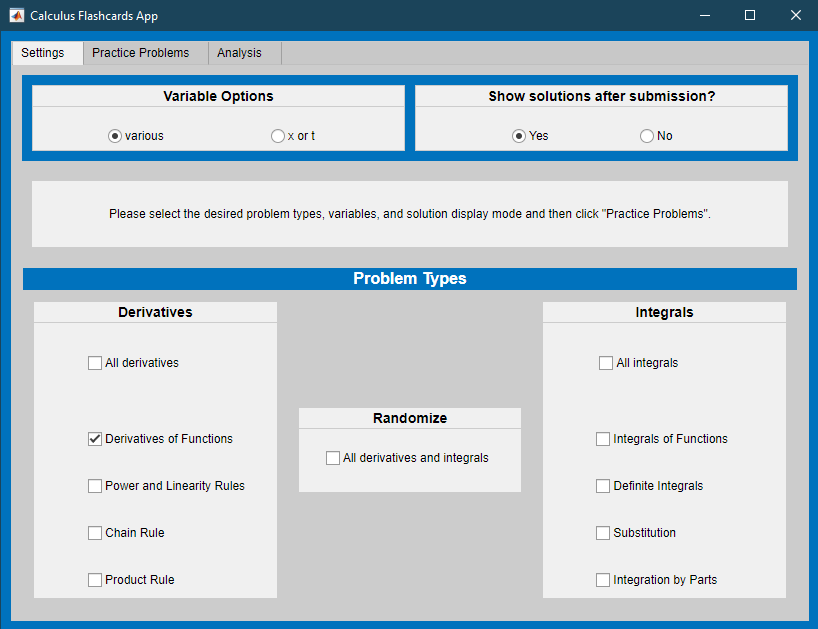](matlab: CalculusFlashcards)

[Calculus Flashcards App](matlab: CalculusFlashcards)

[⇦ Overview](matlab: OpenOverview)

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

**Practice Problem Generating Functions**

Construct a problem to display

function [myFun,varChoice,bds] = genProbType(varOpts)
% genProbType sets up a variable and generates a randomized function
%
% Inputs: varOpts is an array of possible variables
% Outputs: myFun is a symbolic function
%          varChoice is the independent variable
%          [a, b] are the bounds for the definite integral, if required

% Randomly select a variable from the set varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Use genFunDiff to generate simple functions
% genFunDiff is defined in Helper Functions
% The inputs to genFunDiff are the variable varChoice, a range of values
% from which to select coefficients and a value indicating which warnings
% have already been printed during problem generation
        syms f(x) x 
        [f(x),~] = genFunDiff([1 10],x,[1 10],0);
        myFun = f(varChoice);
        bds = randi([-3,4],[1 2]);
        a = bds(1); %#ok<NASGU>
        b = bds(2); %#ok<NASGU>
        % Display the integral problem
        disp("Calculate the integral:")
        displayFormula("F(varChoice) == int(myFun,varChoice,a,b)")
end

Generate appropriate randomized functions

function [myFunc,type] = genFunDiff(bds,var,range,prevFuncType)
syms f(t)                    % Create a symbolic function f(t)
params = randi(bds,[1 4]);   % Randomly choose parameter values
shift = randi([0 max(abs(bds))],1); % Randomly choose a shift that may be 0
sgns = randi([0 1],[1 3]);   % Randomly choose +/- signs
type = randi(range,1);


% For readability, create parameters a,b,c, and d
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, it is only used as a denominator
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^b+c*t^d;
    case 2
        f(t) = a*t^b+t^(d/c);
    case 3
        f(t) = t^a+c*t^b+t^d;
    case 4
        f(t) = t^a+c*t^b+d;
    case 5
        f(t) = a*t^(b);
    case 6
        f(t) = a*t^(b/c);
    case 7
        f(t) = a*log(abs(b)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 8
        f(t) = a*exp(b*t);
        if prevFuncType ~= 8
            disp("Remember that exp(x) is the notation " + ...
                "for $e^x$ in MATLAB. ")
        end
    case 9
        f(t) = a*sin(b*t);
    case 10
        f(t) = a*cos(b*t);
    case 11
        f(t) = a*log(ceil(c/4)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Remember that log(x) is the notation " + ...
                "for a natural logarithm of x in MATLAB. ")
        end
    case 12
        f(t) = a*t^c;
    case 13
        f(t) = a*sin(b*t+d)*exp(b*t);
    case 14
        f(t) = a*cos(b*t+d)*exp(b*t);
end
myFunc = f(var);
end

Handle submissions

function [lastFive,errorCount,totAttempts,adjustCount] = resubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,bds,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
   [lastFive,errorCount] = check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);

elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
                "have been included in the count of errors.")
        else
            disp("The problem generated without an attempt at solution has been " + ...
                "included in the count of errors.")
        end
        [lastFive,errorCount] = check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);
    end
else
        [lastFive,errorCount] = check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);
end
end

Check the submitted solution for correctness

function [lastFive,errorCount] = check1(myFunc,myVar,bds,myAnswer,errorCount,lastFive)
% check1 generates correct answers by integrating and updates
%        errorCount and lastFive
%
% Inputs: myFunc is the symbolic function to differentiate or integrate
%         myVar is the independent variable
%         myAnswer is the symbolic test function or number
%         errorCount is an integer tracking total incorrect attempts
%         lastFive is a vector tracking the last five attempts
% Output: correctAnswer is a symbolic function that is the
%         solution to probType applied to myFunc(myVar) with bds
tol = 1e-3;
correctAnswer = int(myFunc,myVar,bds);
if isequal(myAnswer,str2sym("DNE"))
    myAnswer = nan;
end
lastFive(1:4) = lastFive(2:5);
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif isnan(correctAnswer) && isnan(myAnswer)
    disp("That answer is correct. This integral does not exist.")
    lastFive(5) = 1;
elseif isinf(correctAnswer) && isinf(myAnswer)
    if sign(real(correctAnswer))==sign(myAnswer)
        disp("That answer is correct. The integral diverges towards:")
        disp(correctAnswer)
        lastFive(5) = 1;
    else
        disp("You are correct that the integral diverges, but not about the direction.")
        disp("The integral diverges towards: ")
        disp(correctAnswer)
        lastFive(5) = 0;
    end
elseif ~isreal(myAnswer)
    disp("Your answer should be a finite real number. Please try again.")
elseif abs(double(myAnswer-correctAnswer))<tol
    disp("That answer is rounded. A more precise value is:")
    disp(correctAnswer)
    lastFive(5) = 1;
else
    disp("That is incorrect. Remember to be precise. The correct answer is:");
    displayFormula("int(myFun,varChoice,a,b)==correctAnswer")
    % correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end

Analyze the results and give feedback

function analyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analyzeResults provides feedback in the single problem type case
%    totProbs, errorCount, totAttempts and adjustCount are integers
%    lastFive is a vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % If the user has resubmitted after seeing the solution, respond
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if sum(adjustCount) > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted " + sum(adjustCount) + " times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % If fewer than 5 problems have been attempted, encourage persistence
    str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight,totProbs);
end
disp(str)
end